# Recursive Oscillators

A tool to hear the most common synthetic sinusoids.

Select a preferred value of the angle θ:

theta = 50.71;
theta = (theta*pi)/90;

Select the desired oscillator:

A_bi_quad = [2*cos(theta), -1; 1, 0];
A_dig_wave = [cos(theta), cos(theta)-1; cos(theta)+1, cos(theta)];
A_ea_stagg = [1-(2*sin(theta/2))^2, 2*sin(theta/2); -2*sin(theta/2), 1];
A_quad_stagg = [cos(theta), 1-(cos(theta))^2; -1, cos(theta)];
A_couplestd_quad = [sqrt(1-(sin(theta))^2), sin(theta); -sin(theta), sqrt(1-(sin(theta))^2)];

Osc1 = A_couplestd_quad ;

Choose the initial state:

x1 =1;
x2 =0;

pos1 = [x1; x2];

B=4000;
B_short= 350;
Fs=1000;

sign1 = zeros(2, B);

for i=1:B
    sign1(:, i) = Osc1*pos1;
    pos1 = sign1(:, i);
end 

See the results!

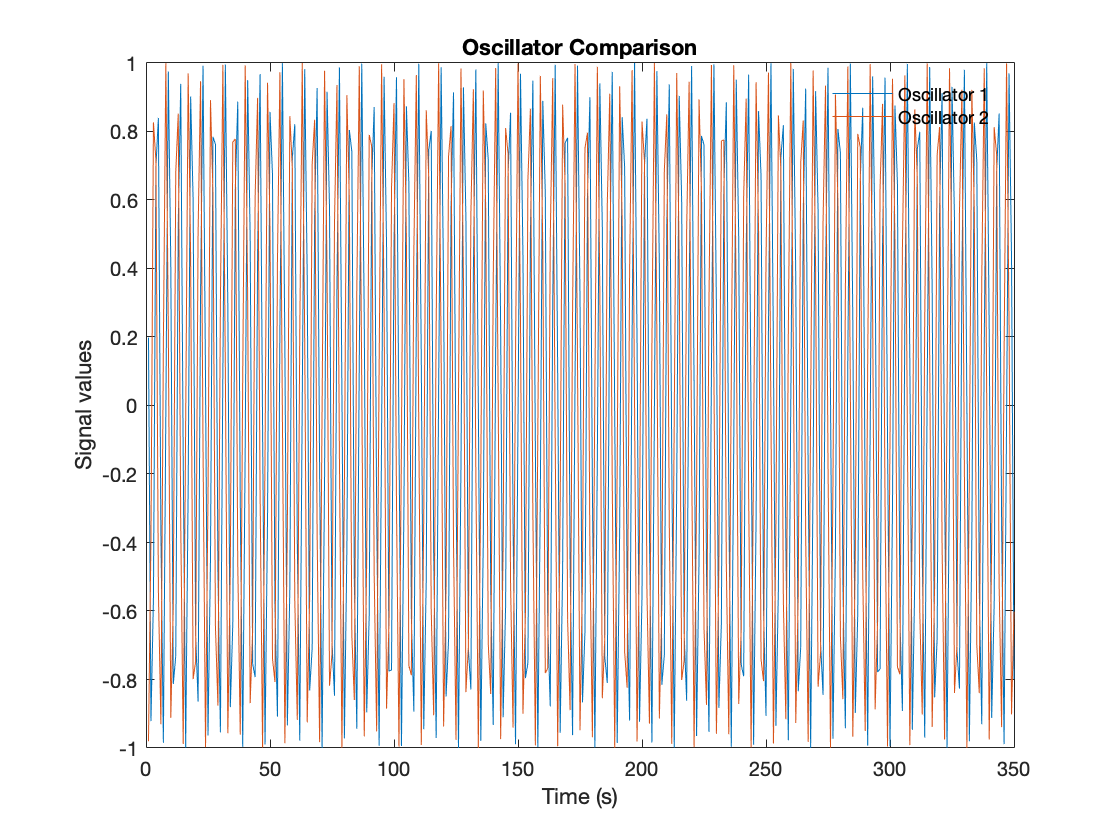

plot(1:B_short, sign1(1, 1:B_short), 1:B_short, sign1(2, 1:B_short))
%legend
title('Oscillator Comparison')
xlabel('Time (s)');
ylabel('Signal values')
legend('Oscillator 1','Oscillator 2')
legend('boxoff')

soundsc(sign1, Fs)
% soundsc(sign2, Fs)